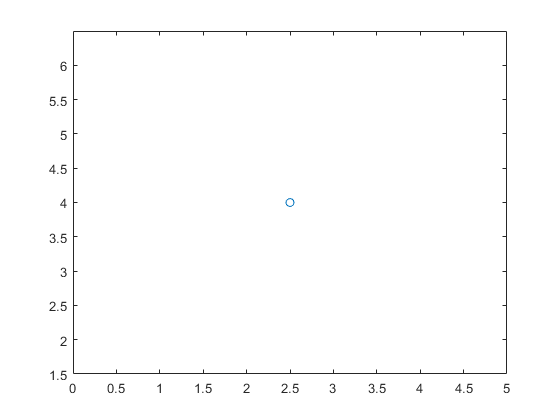

block_width  = 5;
block_height = 2;
x = block_width/2;
y = block_width/2;
flag = 0;
check = 0;

hold off
sprite = plot(x,y,'O');
block_number=3;

hold on 

P_cell_current=0;
P_cell_next=getblock(block_number,block_width,block_height);

xlim([0 block_width]);
ylim([0 block_width]);

i=0;

while i<100
    tic
    if rem(round(y,3),block_height)==0
        block_number=block_number+1;
        P_cell_current=P_cell_next;
        P_cell_next=getblock(block_number,block_width,block_height);
        flag=1;
        check=1;
    else
        flag=0;
    end
    y=y+0.01;
    set(sprite,'XData',[x],'Ydata',[y]);
    if rem(round(y,3),1)==0
        ylim([y-2.5,y+2.5])
    end
    t=toc;
    pause(0.005)
end